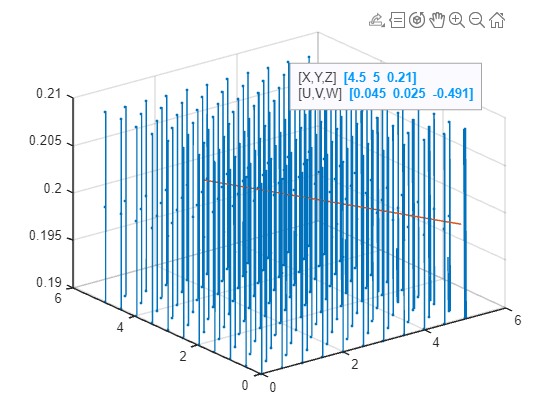

c1 = 1;
c2 = .5;
d1 = .2;
d2 = .1;
I = 1;
E = .1;
gamma = d1/c1;

[X,Y,Z] = meshgrid(0:.5:5, 0:.5:5, .18:.01:.22);
N1 = X .* (c1 .* Z - d1);
N2 = Y .* (c2 .* Z  - d2);
R = I - E .* Z - X .* c1 .* Z - Y .* c2 .* Z;

b = 0:.1:5;
a = (I - E * gamma) / (c1 * gamma) - (c2/c1) * b;
c = linspace(.2,.2,length(a));

q = quiver3(X,Y,Z,N1,N2,R);
q.ShowArrowHead = 'on';
q.Marker = '.';
hold on
plot3(a,b,c)

zlim([.19 .21])